close all
clear all
clc

%% Import dati
opts=detectImportOptions('./data/MiniProjectEFSA.xlsx');
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
data=readtable('./data/MiniProjectEFSA.xlsx', opts);
data.Properties.VariableNames={'response','numberOfAnimals','SD','dose','sex','endpoint'};

weights= 1./((data.SD./sqrt(data.numberOfAnimals)).^2);
gender_female = categorical(data.sex);
endpoint = categorical(data.endpoint);

temp_endpoint=dummyvar(endpoint);
endpoint_1=logical(temp_endpoint(:,1));
endpoint_2=logical(temp_endpoint(:,2));

tbl=table(data.response,data.numberOfAnimals,data.dose,gender_female,endpoint_1,endpoint_2);
tbl.Properties.VariableNames={'response','nOa','dose','female','endpoint_1','endpoint_2'};

mdl = stepwiselm(tbl,'ResponseVar','response','Weights',weights)

1. Adding endpoint_2, FStat = 49.9495, pValue = 4.33235e-07
2. Adding endpoint_1, FStat = 185.5714, pValue = 6.790375e-12
3. Adding dose, FStat = 5.7113, pValue = 0.026816


mdl = Linear regression model:
    response ~ 1 + dose + endpoint_1 + endpoint_2

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                    _________    _________    _______    __________

    (Intercept)        18.868      0.46805     40.312    1.2502e-20
    dose            -0.013995    0.0058562    -2.3898      0.026816
    endpoint_1_1       335.03       22.209     15.085    2.1683e-12
    endpoint_2_1       25.591         1.06     24.142    2.8896e-16


Number of observations: 24, Error degrees of freedom: 20
Root Mean Squared Error: 5.67
R-squared: 0.976,  Adjusted R-Squared: 0.972
F-statistic vs. constant model: 269, p-value = 2.5e-16

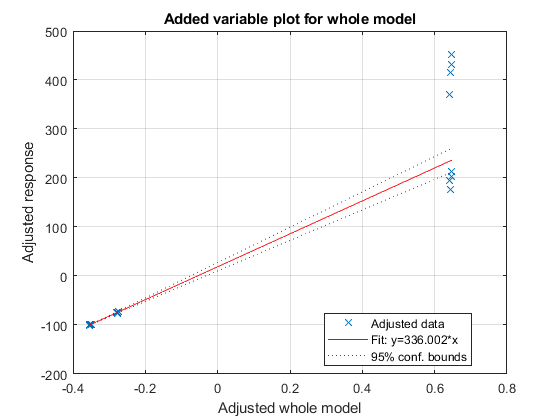

plot(mdl)
grid on

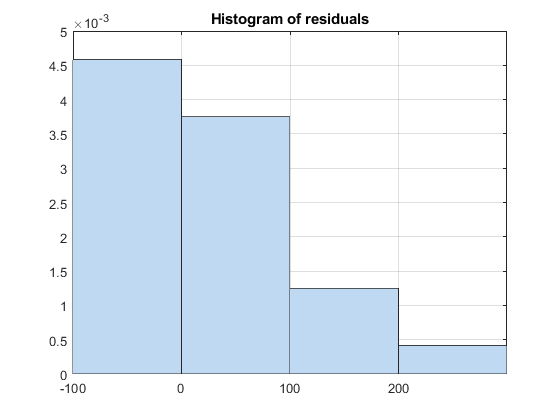

plotResiduals(mdl)
grid on

anova(mdl)

ans = 4×5 table
                  SumSq     DF    MeanSq      F         pValue  
                  ______    __    ______    ______    __________

    dose          183.63     1    183.63    5.7113      0.026816
    endpoint_1    7316.6     1    7316.6    227.56    2.1683e-12
    endpoint_2     18740     1     18740    582.85    2.8896e-16
    Error         643.05    20    32.153                        


coefCI(mdl)

ans =    17.8914   19.8441
   -0.0262   -0.0018
  288.6982  381.3532
   23.3802   27.8025
